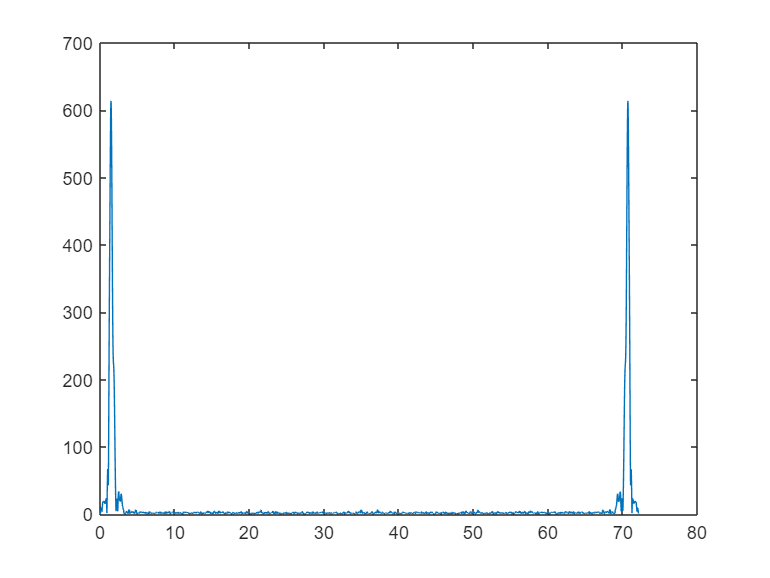

clear;close all;
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency1 = (spectrum{:,1})';
spectrum_intensity1 = (spectrum{:,2})';
%disp("全部光谱信息");
plot(spectrum_frequency1,spectrum_intensity1)

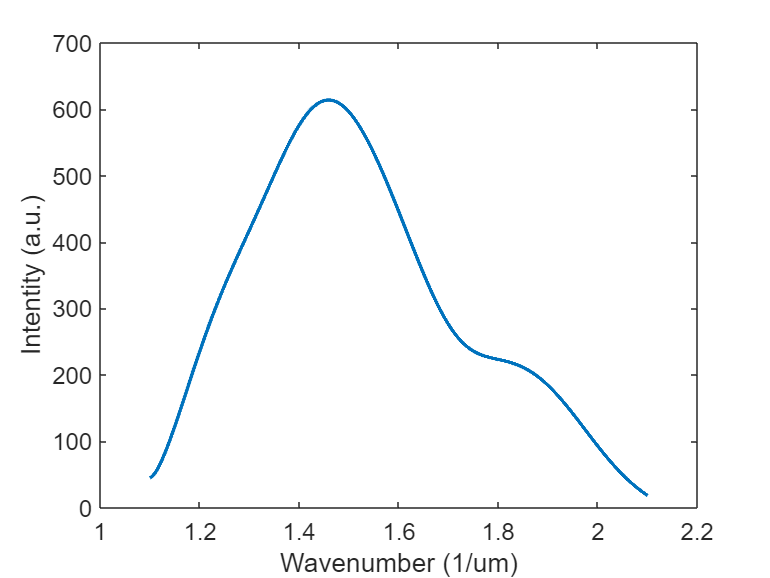

%找出探测器对应的光谱，这里假设是1.1-2.1
spectrum_frequency = linspace(spectrum_frequency1(1),spectrum_frequency1(end),40*length(spectrum_frequency1)); 
%光谱强度三次样条插值
spectrum_intensity = spline(spectrum_frequency1,spectrum_intensity1,spectrum_frequency);

[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency2 = spectrum_frequency(indix_min:indix_max);
spectrum_intensity2 = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency2,spectrum_intensity2,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;

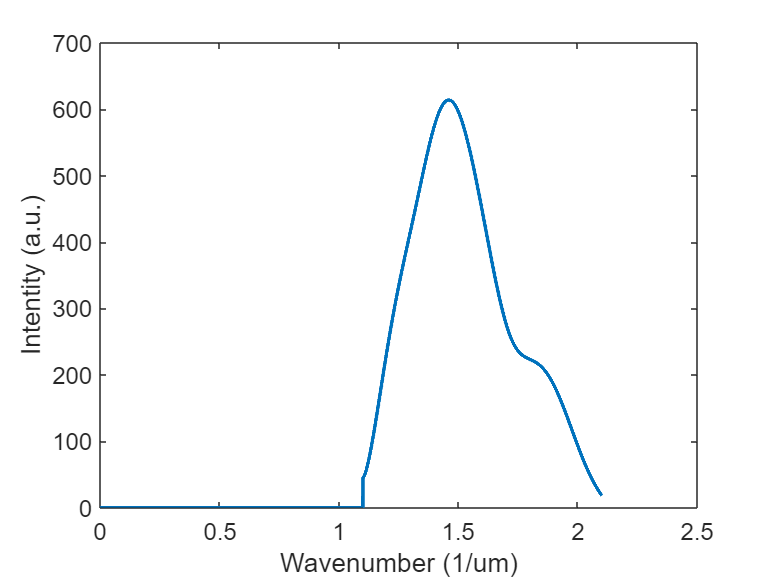


sigma = spectrum_frequency;
windowf = zeros(1,numel(sigma));
windowf(indix_min:indix_max) = 1;
[I_sigma,n] = sigmult(spectrum_intensity2,indix_min:indix_max,windowf,1:length(windowf));

[~, indix_min] = min(abs(sigma-0));
[~, indix_max] = min(abs(sigma-2.1));
sigma = sigma(indix_min:indix_max);
I_sigma = I_sigma(indix_min:indix_max);
% %disp("需要的光谱信息");
plot(sigma,I_sigma,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;


delta = (sigma(end)-sigma(1))/(length(sigma)-1);

%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
I_sigma1 = I_sigma;
sigma1 = sigma;
powerTotal = sum(I_sigma1);
power = sum(I_sigma1.*sigma1);
sigmaA = power/powerTotal

sigmaA = 1.5231

%-----------------------------------
% I_sigma = cirshiftt(I_sigma,-600,length(I_sigma));
plot(sigma,I_sigma,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;



Nifft = 2^20;
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
ifftIsigma = ifft(I_sigma,Nifft);
ifftIsigma = fftshift(ifftIsigma);
zData = zData-zData(end)/2;
intensity = abs(ifftIsigma);
phase = (angle(ifftIsigma));

%找到振幅最大值
[~,index]= max(intensity)

index = 524289

x1 = zData(index)

x1 = 0.0022

y1 = phase(index)

y1 = 0

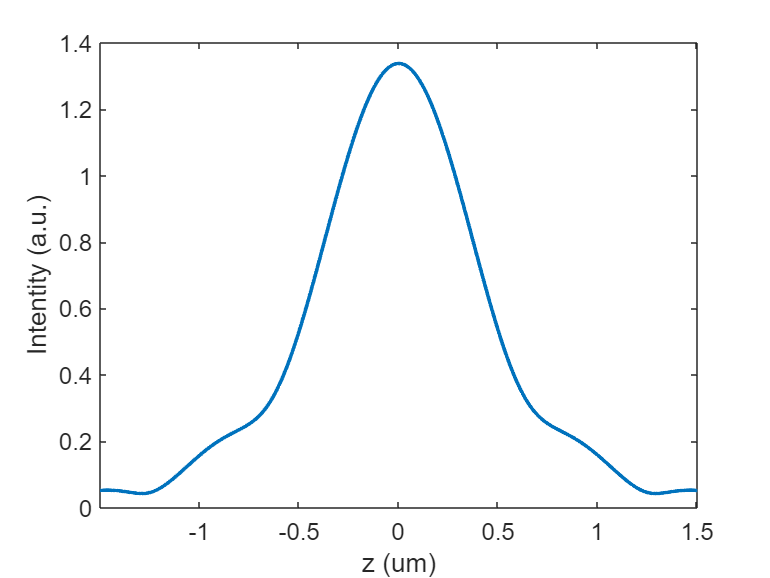


plot(zData,intensity,'LineWidth',2);
xlabel('z (um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;
xlim([x1-1.5 x1+1.5]);

unphase = unwrap(phase);
A = 0.00216645;
AA = unwrap(phase)-unphase(index);
plot(zData-A,AA,'LineWidth',2);%unwrap(phase)-unphase(index)
xlabel('z (um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;
xlim([x1-1 x1+1]);
phhh = unwrap(phase)-unphase(index);
[~, indix_min] = min(abs(zData-(x1-1.5)));
[~, indix_max] = min(abs(zData-(x1+1.5)));
p = polyfit(zData(indix_min:indix_max),phhh(indix_min:indix_max),1)

p =    18.5478   -0.0402


k = polyval(p,zData);
% k = wrapToPi(k);
hold on
plot(zData(indix_min:indix_max)-A,k(indix_min:indix_max),'LineWidth',2);
% D2 = phhh(indix_min:indix_max)-4*pi*1.475989752034065*zData(indix_min:indix_max)+0.040183089660000;
D2 = phhh-polyval(p,zData);
plot(zData(indix_min:indix_max)-A,D2(indix_min:indix_max),'LineWidth',2)
% hold on
p2 = polyfit(zData(indix_min:indix_max),D2(indix_min:indix_max),1)

p2 = 	1.0e+-14 *

   -0.0402    0.2070


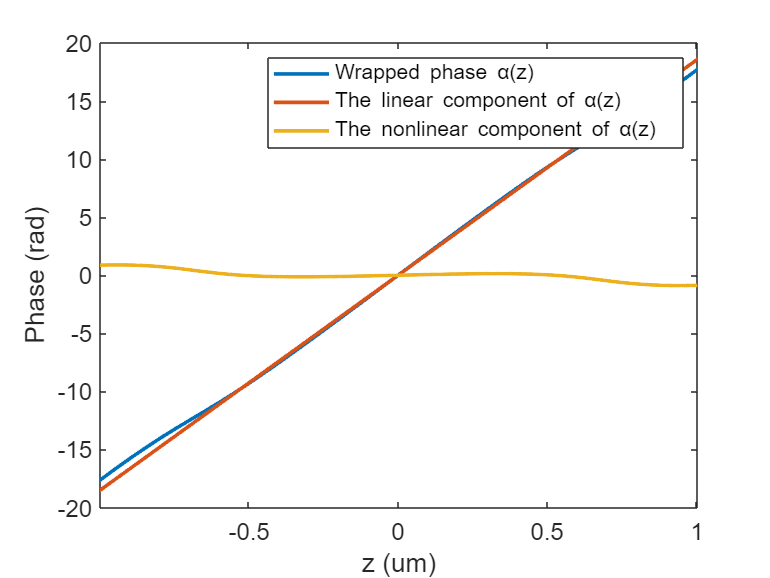

k2 = polyval(p2,zData(indix_min:indix_max));
% plot(zData(indix_min:indix_max),k2,'LineWidth',2);
xlabel('z (um)') 
ylabel('Phase (rad)')
% save("D2.mat","D2")
ax = gca;
ax.FontSize = 13;
hold off

legend('Wrapped phase {\alpha}(z)','The linear component of {\alpha}(z) ','The nonlinear component of {\alpha}(z)');%The least squares line of unwrap phase

% legend('{γ(z)}','{-4πσ_Az}','{Phase spectrum when σ_A=1.5231}');

% [~, indix_min2] = min(abs(sigma-(-0.1658)));
% [~, indix_max2] = min(abs(sigma-0.1658));
% sigma2 = sigma(indix_min2:indix_max2);
% I_sigma2 = I_sigma2(indix_min2:indix_max2);

[~, indix_min2] = min(abs(zData+0.1694));
[~, indix_max2] = min(abs(zData-0.1694));
pAA = polyfit(zData(indix_min2:indix_max2)-x1,AA(indix_min2:indix_max2),1)

pAA =    19.1148    0.0000


kAA = polyval(pAA,zData(indix_min2:indix_max2)-x1);
pBB = polyfit(zData(indix_min2:indix_max2)-x1,D2(indix_min2:indix_max2),1)

pBB =     0.5670    0.0000


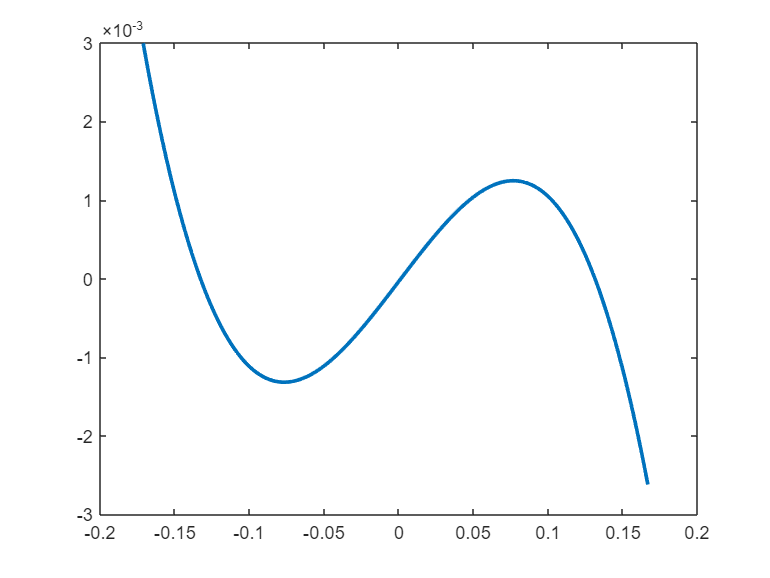

kBB = polyval(pBB,zData(indix_min2:indix_max2)-x1);
plot(zData(indix_min2:indix_max2)-x1,AA(indix_min2:indix_max2)-kAA,'LineWidth',2);

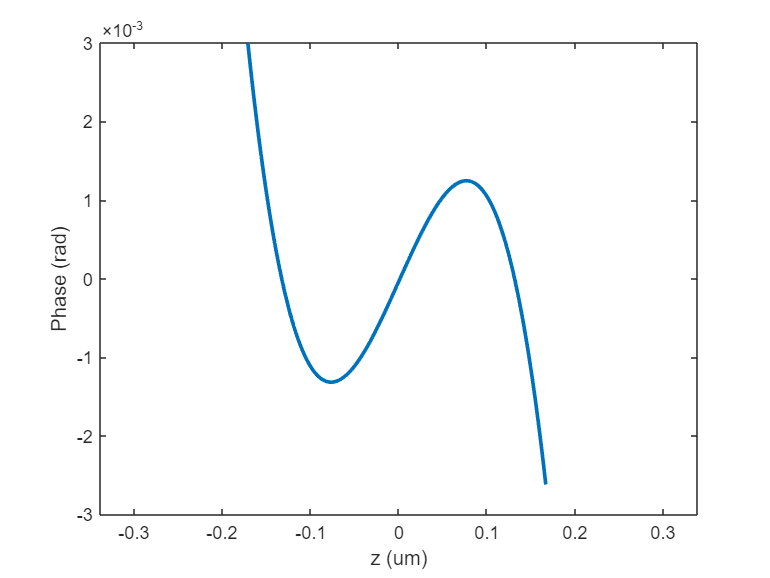

plot(zData(indix_min2:indix_max2)-x1,D2(indix_min2:indix_max2)-kBB,'LineWidth',2);
xlim([-0.3388 0.3388])

xlabel('z (um)') 
ylabel('Phase (rad)')





ydjg = (sigmaA)/delta;
p(2)+round(ydjg)/100*0.000599211

ans = 0.0013




juanju = pAA(1)/(4*pi)

juanju = 1.5211

ydjg2 = (juanju)/delta;
p(2)+round(ydjg2)/100*0.000599211

ans = 0.0012

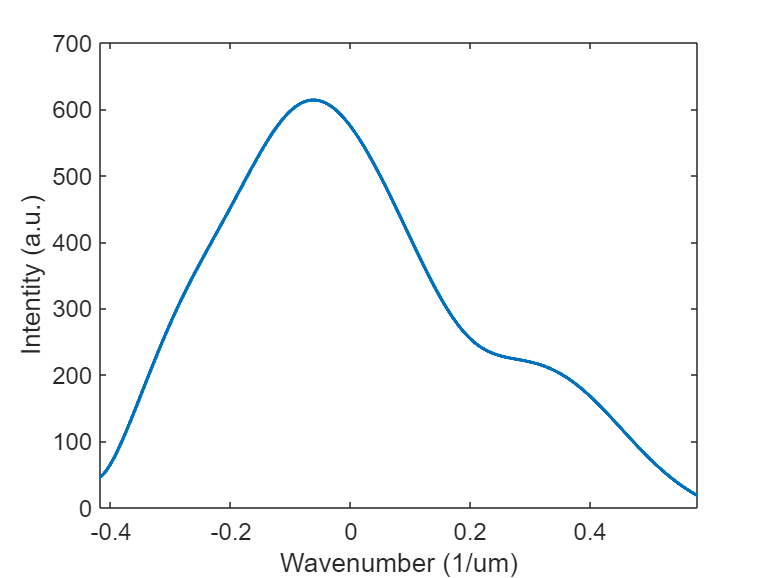



sigma = sigma-juanju;
plot(sigma,I_sigma,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;
xlim([1.103-juanju 2.1-juanju]);


I_sigma1 = I_sigma;
sigma1 = sigma;
powerTotal = sum(I_sigma1);
power = sum(I_sigma1.*sigma1);
sigmaA = power/powerTotal

sigmaA = 0.0020

function [y,n] = sigshift(x,m,k)
%implements y(n) = x(n-k)
%----------------------------------
%[y,n]=sigshift(x,m,k)
%
n = m+k; y = x;
end

function y = cirshiftt(x,m,N)
%Circular shift of m samples wrt size N in sequence x: (time domain)
%-------------------------------------------------------------------
%[y] = cirshftt(x,m,N)
%y = out sequence containing the circular shift 
%x = input sequence of length <= N
%m = sanple shift
%N = size of circular buffer
%Method:y(n) = x((n-m)) mod N)
%Check for length of x
if length(x)>N
    error('N must be >= the length of x');
end
x = [x zeros(1,N-length(x))];
n = [0:1:N-1];
n = mod(n-m,N);
y = x(n+1);
end

function unwrap2(z,intensity_fft,angle_fft)
intensity = intensity_fft;
zData = z;
phase = angle_fft;
[~,index3]= max(intensity);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
if za1<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)+pianyi
za1 = za1-zData(end)+pianyi
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N+pianyi
za1+pianyi
end
zData = zData+pianyi;
plot(zData,intensity);xlim([zData(index3)-20 zData(index3)+15]);
plot(zData,phase);xlim([zData(index3)-3 zData(index3)+3]);
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
end